clear
% ECSE 563 assigmenet 2
% Ali Seifeldin
% https://github.com/Bakalala/MGCILL-ECSE-563

% Question 1
% Setup
run("ieee9_A2.m")

Y = admittance(nfrom, nto, r, x, b);


toler = 1e-4;
maxiter = 20;

[V_nrpf, delta_nrpf, Psl_nrpf, Qgv_nrpf, N_nrpf, time_nrpf,Pf_MW_nrpf, Qf_Mvar_nrpf, Sf_MVA_nrpf] = nrpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter,nfrom,nto)

V_nrpf =     1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9856
    0.9962
    0.9576


delta_nrpf =          0
    0.1688
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759


Psl_nrpf = 71.9547

Qgv_nrpf =    24.0689
   14.4601
   -3.6490
    0.0000
  -30.0000
    0.0000
  -35.0000
    0.0000
  -50.0000


N_nrpf = 4

time_nrpf = 6.1204e-04

Pf_MW_nrpf =    71.9547
   30.7283
  -59.4453
   85.0000
   24.1061
  -75.9893
 -163.0000
   86.5044
  -40.9601


Qf_Mvar_nrpf =    24.0689
    7.1102
    0.7206
   -3.6490
   15.0574
   -3.3616
    2.2762
   12.6510
  -27.6481


Sf_MVA_nrpf =    75.8735
   31.5402
   59.4497
   85.0783
   28.4224
   76.0637
  163.0159
   87.4246
   49.4180


% Question 2
% Setup
run("ieee9_A2.m")

Y = admittance(nfrom, nto, r, x, b);


toler = 1e-4;
maxiter = 20;

[V_decpf, delta_decpf, Psl_decpf, Qgv_decpf, N_decpf, time_decpf,Pf_MW_decpf, Qf_Mvar_decpf, Sf_MVA_decpf] = decpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter,nfrom,nto)

V_decpf =     1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9856
    0.9962
    0.9576


delta_decpf =          0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759


Psl_decpf = 71.9555

Qgv_decpf =    24.0684
   14.4594
   -3.6497
   -0.0002
  -29.9996
    0.0005
  -34.9996
    0.0002
  -49.9995


N_decpf = 7

time_decpf = 9.4108e-04

Pf_MW_decpf =    71.9555
   30.7303
  -59.4457
   84.9998
   24.1060
  -75.9893
 -162.9997
   86.5038
  -40.9603


Qf_Mvar_decpf =    24.0684
    7.1099
    0.7207
   -3.6497
   15.0573
   -3.3613
    2.2768
   12.6509
  -27.6476


Sf_MVA_decpf =    75.8742
   31.5421
   59.4500
   85.0781
   28.4222
   76.0636
  163.0156
   87.4240
   49.4180



%comparing nrpf to decpf

V_diff =  V_decpf - V_nrpf

V_diff = 1.0e-06 *

         0
    0.0000
         0
    0.3009
    0.2347
    0.3749
    0.5871
    0.3907
    0.7153


delta_diff =  delta_decpf - delta_nrpf

delta_diff = 1.0e-05 *

         0
   -0.2042
   -0.2049
   -0.0483
   -0.2490
   -0.1907
   -0.1753
   -0.1810
   -0.0735


Psl_diff =  Psl_decpf - Psl_nrpf

Psl_diff = 8.4850e-04

Qgv_diff = Qgv_decpf - Qgv_nrpf

Qgv_diff = 1.0e-03 *

   -0.4872
   -0.6596
   -0.6511
   -0.2056
    0.3881
    0.4601
    0.4098
    0.1417
    0.4370


% results are pretty similar

N_diff = N_decpf - N_nrpf

N_diff = 3

% Needs 3 more iterations using decpf
time_diff = time_decpf - time_nrpf

time_diff = 3.2904e-04

% DECPF is still faster


% Question 3
% Setup
run("ieee9_A2.m")

Y = admittance(nfrom, nto, r, x, b);


toler = 1e-4;
maxiter = 20;
[V_fastdecpf, delta_fastdecpf, Psl_fastdecpf, Qgv_fastdecpf, N_fastdecpf, time_fastdecpf,Pf_MW_fastdecpf, Qf_Mvar_fastdecpf, Sf_MVA_fastdecpf] = fastdecpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter,nfrom,nto)

V_fastdecpf =     1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9856
    0.9962
    0.9576


delta_fastdecpf =          0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759


Psl_fastdecpf = 71.9550

Qgv_fastdecpf =    24.0677
   14.4591
   -3.6502
   -0.0006
  -29.9982
    0.0003
  -34.9996
    0.0002
  -49.9992


N_fastdecpf = 7

time_fastdecpf = 2.0825e-04

Pf_MW_fastdecpf =    71.9550
   30.7299
  -59.4456
   84.9998
   24.1060
  -75.9892
 -162.9996
   86.5039
  -40.9602


Qf_Mvar_fastdecpf =    24.0677
    7.1090
    0.7213
   -3.6502
   15.0573
   -3.3613
    2.2771
   12.6507
  -27.6474


Sf_MVA_fastdecpf =    75.8734
   31.5415
   59.4500
   85.0781
   28.4222
   76.0635
  163.0155
   87.4240
   49.4178



%comparing nrpf to fastdecpf

V_diff =  V_fastdecpf - V_nrpf

V_diff = 1.0e-05 *

         0
    0.0000
         0
    0.0720
    0.1607
    0.0660
    0.0836
    0.0585
    0.1288


delta_diff =  delta_fastdecpf - delta_nrpf

delta_diff = 1.0e-05 *

         0
   -0.1658
   -0.1460
   -0.0149
   -0.1893
   -0.1290
   -0.1152
   -0.1333
   -0.0259


Psl_diff =  Psl_fastdecpf - Psl_nrpf

Psl_diff = 3.0717e-04

Qgv_diff = Qgv_fastdecpf - Qgv_nrpf

Qgv_diff =    -0.0012
   -0.0010
   -0.0011
   -0.0006
    0.0018
    0.0003
    0.0004
    0.0001
    0.0008



% results are pretty similar

N_diff = N_fastdecpf - N_nrpf

N_diff = 3

% Needs 3 more iterations using fastdecpf
time_diff = time_fastdecpf - time_nrpf

time_diff = -4.0379e-04

% fastdecpf is still faster

%comparing decpf to fastdecpf

V_diff =  V_fastdecpf - V_decpf

V_diff = 1.0e-05 *

         0
   -0.0000
         0
    0.0419
    0.1372
    0.0285
    0.0249
    0.0194
    0.0572


delta_diff =  delta_fastdecpf - delta_decpf

delta_diff = 1.0e-06 *

         0
    0.3838
    0.5890
    0.3340
    0.5962
    0.6163
    0.6011
    0.4772
    0.4766


Psl_diff =  Psl_fastdecpf - Psl_decpf

Psl_diff = -5.4133e-04

Qgv_diff = Qgv_fastdecpf - Qgv_decpf

Qgv_diff =    -0.0008
   -0.0003
   -0.0005
   -0.0004
    0.0014
   -0.0001
    0.0000
   -0.0000
    0.0003



% results are pretty similar

N_diff = N_fastdecpf - N_decpf

N_diff = 0

% Same number of iterations
time_diff = time_fastdecpf - time_decpf

time_diff = -7.3283e-04

% fastdecpf is faster than decpf

% Question 4
% Setup
run("ieee9_A2.m")

[delta_dcpf, Psl_dcpf, Pf_dcpf, time_dcpf] = dcpf(nfrom, nto, x, is, Pg, Pd, Sbase)

delta_dcpf =          0
    0.1710
    0.0883
   -0.0386
   -0.0652
    0.0385
    0.0144
    0.0691
   -0.0709


Psl_dcpf = 67.0000

Pf_dcpf =    67.0000
   28.9674
  -61.0326
   85.0000
   23.9674
  -76.0326
 -163.0000
   86.9674
  -38.0326


time_dcpf = 0.0013


%comparing dcpf to fastdecpf

delta_diff =  delta_dcpf - delta_fastdecpf

delta_diff =          0
    0.0022
    0.0051
    0.0034
    0.0049
    0.0049
    0.0035
    0.0028
    0.0050


Psl_diff =  Psl_dcpf - Psl_fastdecpf

Psl_diff = -4.9550

% results are pretty similar for deltas, off by 3 decimal points, but PSL
% is different doesnt account for Q
time_diff = time_dcpf - time_fastdecpf

time_diff = 0.0011

% fastdecpf is faster than dcpf

%comparing dcpf to to decpf

delta_diff =  delta_dcpf - delta_decpf

delta_diff =          0
    0.0022
    0.0051
    0.0034
    0.0049
    0.0049
    0.0035
    0.0028
    0.0050


Psl_diff =  Psl_dcpf - Psl_decpf

Psl_diff = -4.9555

% results are pretty similar for deltas, off by 3 decimal points, but PSL
% is different doesnt account for Q
time_diff = time_dcpf - time_decpf

time_diff = 4.0504e-04

% decpf is faster than dcpf

%comparing dcpf to to nrpf

delta_diff =  delta_dcpf - delta_nrpf

delta_diff =          0
    0.0022
    0.0051
    0.0034
    0.0049
    0.0049
    0.0035
    0.0028
    0.0050


Psl_diff =  Psl_dcpf - Psl_nrpf

Psl_diff = -4.9547

% results are pretty similar for deltas, off by 3 decimal points, but PSL
% is different doesnt account for Q
time_diff = time_dcpf - time_nrpf

time_diff = 7.3408e-04

% dcpf is fsdter than nrpf

% Question 5
Pf_MW = Pf_MW_fastdecpf;
Sf_MVA = Sf_MVA_fastdecpf;
% Branch 1,2,3 and 9 are the ones with the main differences between the AC
% and DC model if we compare to the active power. 
Pf_diff = Pf_MW-Pf_dcpf

Pf_diff =     4.9550
    1.7626
    1.5870
   -0.0002
    0.1386
    0.0434
    0.0004
   -0.4635
   -2.9276


% We also see that the DC power flow and the apparent power have larger
% differences, specefically in line 1,2,3 5 and 9.  
Sf_diff = Sf_MVA-abs(Pf_dcpf)

Sf_diff =     8.8734
    2.5741
   -1.5826
    0.0781
    4.4548
    0.0309
    0.0155
    0.4566
   11.3852



% the DC model is faster computationally, but it only captures real power transfer driven by phase angles, 
% while the AC model also includes voltage magnitude effects, line resistance, and reactive power 

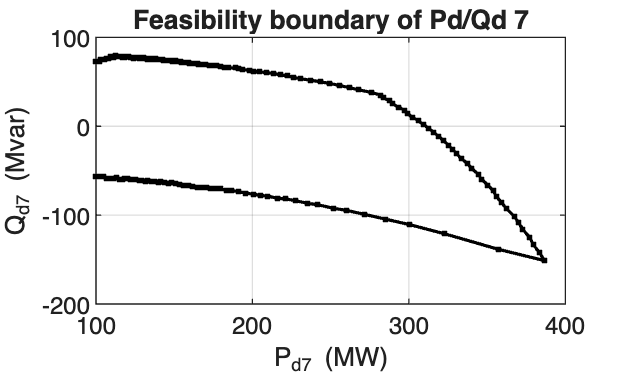

% Question 6
% Setup
run("ieee9_A2.m")
Y = admittance(nfrom, nto, r, x, b);

% Settings for the sweep
phis   = linspace(-pi/2, pi/2, 181);   % directions in (Pd7,Qd7) with P>=0
step  = 2;                            % step size
toler = 1e-4;
maxiter = 20;
Vmin   = 0.95; 
Vmax   = 1.05;

% Base point at bus 7 from vectors
Pd7_base = Pd(7); 
Qd7_base = Qd(7);

boundary = nan(numel(phis),2);

% do this for each angle, making sure P > 0
for k = 1:numel(phis)
    c = cos(phis(k)); 
    s = sin(phis(k));
    lower_b = 0; upper_b = 0;

    % find first unfeasible soluton and track last feasible solution 
    while true
        try_b = upper_b + step;
    
        Pd_try = Pd; Qd_try = Qd;
        Pd_try(7) = Pd7_base + try_b*c;
        Qd_try(7) = Qd7_base + try_b*s;
    
        
        [Vmag, ~, ~, ~, ~, ~] = fastdecpf(Y, is, ipq, ipv, Pg, Qg, Pd_try, Qd_try, V0, Sbase, toler, maxiter, nfrom, nto);
        vmin = min(Vmag); vmax = max(Vmag);

        ok = (vmin >= Vmin) && (vmax <= Vmax);

    
        if ok
            upper_b = try_b;
        else
            break;
        end
    
    end

    % Bisection to refine the boundary point 
    for it = 1:maxiter
        middle_b = 0.5*(lower_b + upper_b);

        Pd_try = Pd;  Qd_try = Qd;
        Pd_try(7) = Pd7_base + middle_b*c;
        Qd_try(7) = Qd7_base + middle_b*s;

        try
            [Vmag, ~, ~, ~, ~, ~] = fastdecpf(Y, is, ipq, ipv, Pg, Qg, Pd_try, Qd_try, V0, Sbase, toler, maxiter, nfrom, nto);
            ok_mid = all(Vmag >= Vmin & Vmag <= Vmax);
        catch
            ok_mid = false;
        end

        if ok_mid 
            lower_b = middle_b; 
        else 
            upper_b = middle_b; 
        end
        if abs(upper_b - lower_b) < toler
            break; 
        end
    end

    boundary(k,:) = [Pd7_base + lower_b*c, Qd7_base + lower_b*s];
end

% Plot  feasibility boundary
figure; plot(boundary(:,1), boundary(:,2), 'k.-', 'LineWidth', 1.2); grid on
xlabel('P_{d7} (MW)'); ylabel('Q_{d7} (Mvar)');
title('Feasibility boundary of Pd/Qd 7');

% Question 7

% Setup
run("ieee9_A2.m")

toler = 1e-4;
maxiter = 20;

removals = [4 5;
            4 9;
            5 6;
            6 7;
            7 8;
            8 9];

for k = 1:size(removals,1)
    run("ieee9_A2.m")
    i = removals(k,1); 
    j = removals(k,2);

    % find matching corridors (direction-insensitive)
    idx = find( (nfrom==i & nto==j) | (nfrom==j & nto==i) );

    if ~isempty(idx)
        fprintf('Removing line %d-%d (index %d)\n', i, j, idx);
        nfrom(idx) = [];
        nto(idx)   = [];
        r(idx)     = [];
        x(idx)     = [];
        b(idx)     = [];
    else
        fprintf('Line %d-%d not found, skipping.\n', i, j);
    end

    Y = admittance(nfrom, nto, r, x, b);
    [V_nrpf, delta_nrpf, Psl_nrpf, Qgv_nrpf, N_nrpf, time_nrpf,Pf_MW_nrpf, Qf_Mvar_nrpf, Sf_MVA_nrpf] = nrpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter,nfrom,nto);

    ok = all(V_nrpf >= 0.95 & V_nrpf <= 1.05)
end

Removing line 4-5 (index 2)


ok = logical
   0


Removing line 4-9 (index 9)


ok = logical
   0


Removing line 5-6 (index 3)


ok = logical
   0


Removing line 6-7 (index 5)


ok = logical
   0


Removing line 7-8 (index 6)


ok = logical
   0


Removing line 8-9 (index 8)


ok = logical
   0



% None of these scenarios are acceptable. as you can see, the V are always
% outside the range of .95 and 1.05